绘图解起飞重量方程

m=6629.5:0.0001:6629.6;
ym=0.6908*m-1.5288*(m.^0.84)-2100;
plot(m,ym);

数据

F=33723000;alf=3.21*pi/180;
C1=0.0134;C2=0.403;C3=1.09;%C1阻力系数，C2升力系数，C3起飞最大升力系数
S=23;Pro=1.29;m=6630;g=9.8;

飞行包线

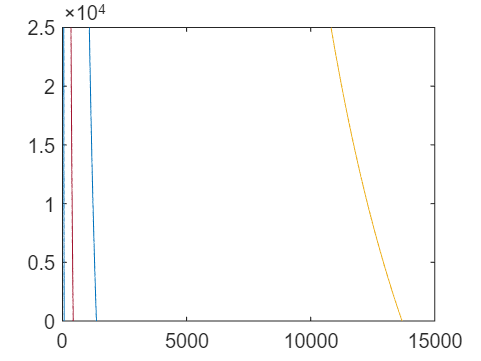

C1=0.0134;C2=0.403;C3=1.09;F=33723;S=23;m=6630;g=9.8;
h001=0:100:25000;
t001=-0.006*h001+27;
Pro=-0.004671*t001+1.295;
Vmax=(2*F./(C1*Pro*S)).^(1/2);
Vmin=(2*m*g./(C3*Pro*S)).^(1/2);
plot(Vmax,h001);
hold on;
plot(Vmin,h001);

给定高度的爬升率

V=(Vmax+Vmin)/2; % xxxm下速度
D=0.5.*Pro.*V.^2.*S.*C2;
Vz=((F.*cos(alf)-D).*V)/m*g

Vz =  -332.4322 -332.0344 -331.6380 -331.2430 -330.8495 -330.4573 -330.0665 -329.6771 -329.2891 -328.9025 -328.5172 -328.1332 -327.7506 -327.3694 -326.9894 -326.6108 -326.2335 -325.8575 -325.4828 -325.1094 -324.7373 -324.3664 -323.9968 -323.6285 -323.2614 -322.8956 -322.5310 -322.1676 -321.8055 -321.4446 -321.0849 -320.7264 -320.3691 -320.0130 -319.6581 -319.3043 -318.9517 -318.6003 -318.2501 -317.9010 -317.5530 -317.2062 -316.8606 -316.5160 -316.1726 -315.8303 -315.4891 -315.1490 -314.8100 -314.4721
